# LIME可解释性分析

对ImageNet预训练图像分类模型，运行LIME(Locally Interpretable Model-agnostic Explanations)可解释性分析。

可视化某个输入图像，某个图块区域，对模型预测为某个类别的贡献影响。

参考教程：https://ww2.mathworks.cn/help/deeplearning/ug/understand-network-predictions-using-lime.html

参考教程：https://ww2.mathworks.cn/help/deeplearning/ref/imagelime.html

2022-11-1

## LIME算法简介

LIME是通用的机器学习可解释性分析方法。

使用“可解释特征”，训练“可解释模型”，在“特定样本的局部线性邻域”拟合“原模型”。

通过可解释模型的特征权重，定量分析特征重要度，及特定样本的某个特征对模型预测某一类的影响。

在表格、文本、图像等数据模态上都表现出良好的可信性和可解释性。

MATLAB的深度学习工具箱，内置了 `imageLIME` 函数，用于对深度学习进行基于LIME的可解释性分析，对于图像数据，步骤如下：

1.将待测图像划分为若干图块

2.对于每个图块，随机保留或将像素抹为平均值，生成若干新图像，也就是原始样本的邻域样本

3.用每个图块是否被抹去的0-1向量，表示样本的“可解释特征”

4.将每个邻域样本输入原始模型中，获得预测结果

5.用可解释特征和预测结果，训练简单的可解释模型（比如线性分类模型）

6.可解释模型近似反映了原始模型在指定样本邻域的行为，它的特征权重，就反映了每个图块的特征重要度，对模型预测为某一类的影响

## 载入预训练图像分类模型

net = googlenet;

inputSize = net.Layers(1).InputSize(1:2); % 获取模型输入图像尺寸
classes = net.Layers(end).Classes;        % 获取模型输出类别名称

## 载入测试图像

img = imread("sherlock.jpg");
img = imresize(img,inputSize); % 缩放至模型要求的输入尺寸

## 输入图像分类模型预测，获取top-3类别

[YPred, scores] = classify(net, img);
[~,topIdx] = maxk(scores, 3);
topScores = scores(topIdx);
topClasses = classes(topIdx);

## 可视化图像分类预测结果

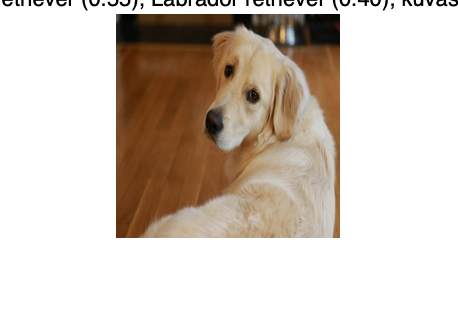

imshow(img)
titleString = compose("%s (%.2f)",topClasses,topScores');
title(sprintf(join(titleString, "; ")));

模型预测置信度最高的类别是 `golden retriever，同时，预测为 Labrador retriever 的置信度也较高。`

## 使用imageLIME函数，实现LIME可解释性分析

map = imageLIME(net,img, YPred);

## 可视化“`golden retriever`”类别的可解释性分析图

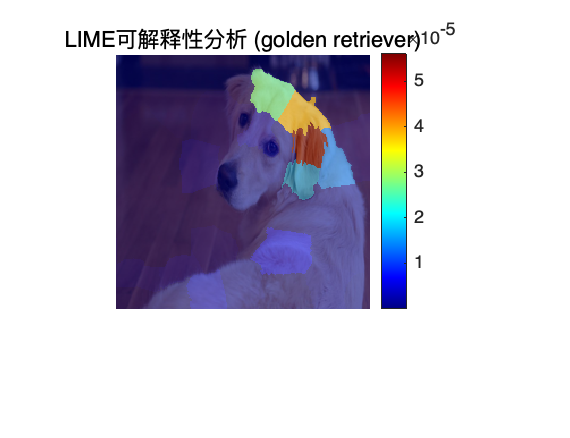

figure
imshow(img,'InitialMagnification',150)
hold on
imagesc(map,'AlphaData',0.5)
colormap jet
colorbar

title(sprintf("LIME可解释性分析 (%s)", YPred))
hold off

图块带颜色，表示该图块对于可解释线性模型预测为指定类别，有较大权重和影响。

对于类别 `golden retriever`，模型更关注上额、耳朵、脖子。

## 可视化“`Labrador retriever`”类别的可解释性分析图

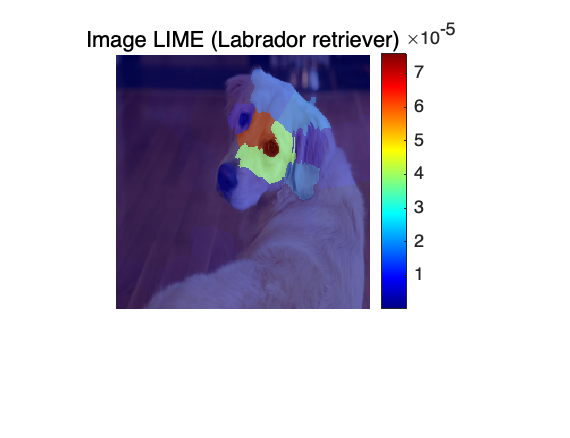

secondClass = topClasses(2);
map = imageLIME(net, img, secondClass);
figure;
imshow(img,'InitialMagnification',150)
hold on
imagesc(map,'AlphaData',0.5)
colormap jet
colorbar

title(sprintf("Image LIME (%s)",secondClass))
hold off

对于类别 `Labrador retriever` ，模型更关注眼睛和鼻子。

## 计算更细粒度的LIME热力图

map = imageLIME(net,img,"golden retriever", ...
    "Segmentation","grid",...           % 将图像分为若干小方格，而非不规则的超像素图块
    "OutputUpsampling","bicubic",...    % 将热力图缩放至原图尺寸的上采样方法，双线性插值
    "NumFeatures",100,...               % 可解释特征个数（小方格个数），64 代表 8x8 网格
    "NumSamples",6000,...               % 生成的邻域样本个数
    "Model","linear");                  % 可解释模型：线性回归模型

## 可视化

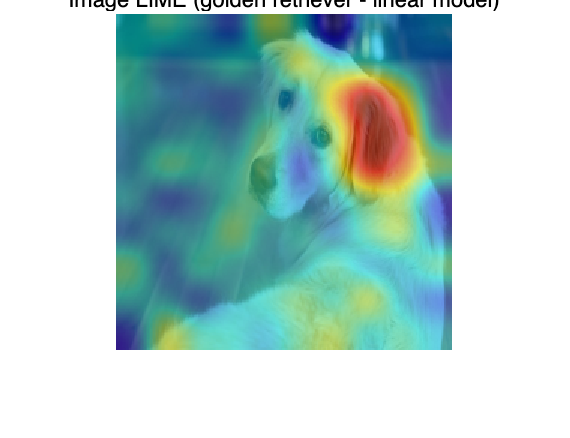

imshow(img,'InitialMagnification', 150)
hold on
imagesc(map,'AlphaData',0.5)
colormap jet

title(sprintf("Image LIME (%s - linear model)", ...
    YPred))
hold off

和 Grad-CAM 热力图效果类似，对于类别 `golden retriever`，模型更关注耳朵、脖子区域。

## 单独显示对指定类别影响较大的图块

计算LIME可解释性分析图

[map, featureMap, featureImportance] = imageLIME(net, img, YPred);

选出影响最大的前n个图块

n = 4;
[~,idx] = maxk(featureImportance, n);

单独显示n个图块

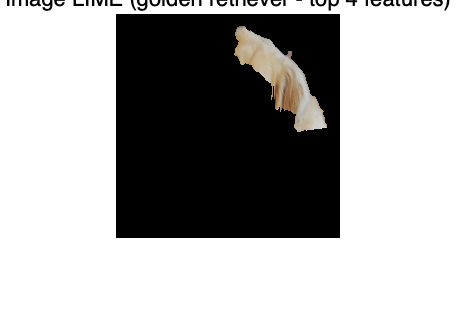

mask = ismember(featureMap,idx);
maskedImg = uint8(mask).*img;

figure
imshow(maskedImg);

title(sprintf("Image LIME (%s - top %i features)", YPred, n))